# Validation of Physics-Based Image Systems Simulation with 3D Scenes

## Figure 8

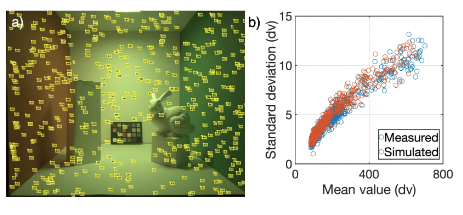

Fig. 8. Sensor noise estimated in measurement and simulation. (a) We randomly tested many small (10 `×` 10) image regions. We accepted a region for a noise estimate if it contained no dead pixels and the values were consistent with a uniform spectral irradiance. The yellow boxes show the regions that were accepted. See text for details. (b) Within each uniform region, the standard deviation increases with mean signal level. The simulated data match well with the measurement.

% Noise analysis

%%
ieInit;

%%
sensorDir = fullfile(cboxRootPath, 'local',...
                    'figures', 'qualitative');
%%
% Center
% Measurement
sensorMeasPath = fullfile(sensorDir, 'sensorMeasCtr.mat');
load(sensorMeasPath, 'sensorMeasCtr');

% Simulation
sensorSimPath = fullfile(sensorDir, 'sensorSimCtr.mat');
load(sensorSimPath, 'sensorSimCtr');


%% Parameter initialization
nROI = 500;
width = 10; height = 10;
%% Simulation

roiSelectsSim = cbSensorUniformROISample(sensorSimCtr,...
                                        'nsamples', nROI,...
                                        'sz', [width, height]);

[udataSelectsSim, prevImgROISim] = cbRoiSelect(sensorSimCtr, roiSelectsSim);

%% Measurement
roiSelectsMeas = cbSensorUniformROISample(sensorMeasCtr,...
                                            'nsamples', nROI,...
                                            'sz', [width, height]);

[udataSelectsMeas, prevImgROIMeas] = cbRoiSelect(sensorMeasCtr, roiSelectsMeas);

ieNewGraphWin; imshow(prevImgROIMeas);

%% Draw noise comparison curve
stdMeas = zeros(1, nROI); meanMeas = zeros(1, nROI);
stdSim = zeros(1, nROI); meanSim = zeros(1, nROI);
ieNewGraphWin; hold all;
for ii=1:nROI
    stdMeas(ii) = udataSelectsMeas{ii}.std(2);
    meanMeas(ii) = udataSelectsMeas{ii}.mean(2);
    stdSim(ii) = udataSelectsSim{ii}.std(2);
    meanSim(ii) = udataSelectsSim{ii}.mean(2);
end
% Measurement
p1 = plot(meanMeas, stdMeas, 'o');
p1.MarkerEdgeColor = [0 0.4470 0.7410];
p1.MarkerSize = 8;
% Simulation
p2 = plot(meanSim, stdSim, 'o');
p2.MarkerEdgeColor = [0.8500 0.3250 0.0980];
p2.MarkerSize = 8;

l = legend('Measured', 'Simulated');
l.FontSize = 10;
ylabel('Standard deviation (dv)'); xlabel('Mean value (dv)');
axis square; box on; grid on; ylim([0 20]); xlim([0 800]);